# Reaction Kinetics - ODEs

Assume we have a reaction follows the scheme below: 

Eq. 4.1                                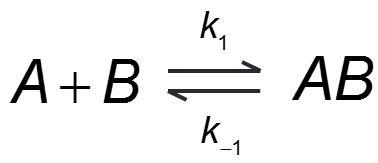

Remember that we saw that the rate of change of each species is as follows

Eq. 4.2                        $\frac{\mathrm{d}\left\lbrack A\right\rbrack }{\mathrm{d}t}=\frac{\mathrm{d}\left\lbrack B\right\rbrack }{\mathrm{d}t}=-k_1 \left\lbrack A\right\rbrack \left\lbrack B\right\rbrack +k_{-1} \left\lbrack \mathit{\text{AB}}\right\rbrack$

Eq. 4.3                               $\frac{\mathrm{d}\left\lbrack \mathit{\text{AB}}\right\rbrack }{\mathrm{d}t}=+k_1 \left\lbrack A\right\rbrack \left\lbrack B\right\rbrack -k_{-1} \left\lbrack \mathit{\text{AB}}\right\rbrack$

Given this set of ordinary differential equations (ODEs), we can simulate the time course of the reaction using the initial concentrations of the individual species, a so-called initial value problem.

MATLAB has built-in solvers for solving a series of ODEs.  In an initial value problem, the ODE is solved by starting from an initial state.  Using the initial conditions (*initialConc*) and the period of time over which the answer is to be obtained (*timespan*), the solution is found iteratively. 

The series of ODEs are contained in the function *reactionFun*, which is defined below.  Note, functions that are defined and called within the script must appear at the end of the file.  

Here we'll assume that the initial concentrations are $\left\lbrack A\right\rbrack \left(0\right)=10\text{ }\mu \mathrm{M}$,$\left\lbrack B\right\rbrack \left(0\right)=5\text{ }\mu \mathrm{M}$,$\left\lbrack \mathit{AB}\right\rbrack \left(0\right)=1\text{ }\mu \mathrm{M}$,  that $k_1 =1\text{ }\mu {\mathrm{M}}^{-1} {\mathrm{s}}^{-1}$ and $k_{-1} =0\ldotp 1\text{ }{\mathrm{s}}^{-1}$ and solve over a 10 second window.

initialConc = [10 5 1]; %uM, initial concentrations
timespan = [0 10]; %s, time span of the reaction

The built-in solver (ode45) solves the system of ODEs contained in the function *reactionFun* over the defined time span, using the intitial values given.  The solver then returns the solution in two arrarys: 'T' - is the time over which solutions are determined; and 'Y' - contains the values for each species at the respective time points, each column contains a single species (*A* = Y(:,1); *B* = Y(:,2); and *AB* = Y(:,3))

[T,Y] = ode45(@reactionFun,timespan,initialConc);

%plot the results
figure(1);clf
plot(T,Y(:,1),'b-');hold on;
plot(T,Y(:,2),'r-')
plot(T,Y(:,3),'k-')
xlabel('time (sec)','FontSize',12)
ylabel('concentration (\muM)','FontSize',12)
legend('[A]','[B]','[AB]')

What happens if you change the rates of reaction?  For example, change $k_1 =0\ldotp 1\mu {\mathrm{M}}^{-1} {\mathrm{s}}^{-1}$ in the *reactionFun* below, and then run the code again

## Michaelis-Menten Enzyme Kinetics

Let's build the complexity of the reaction above.  Now assume that *AB* acts as an enzyme that converts *C *to *D*.  Additionally, a second enzyme (*E*) converts *D* back to *C *as follows

Eq. 4.4                                     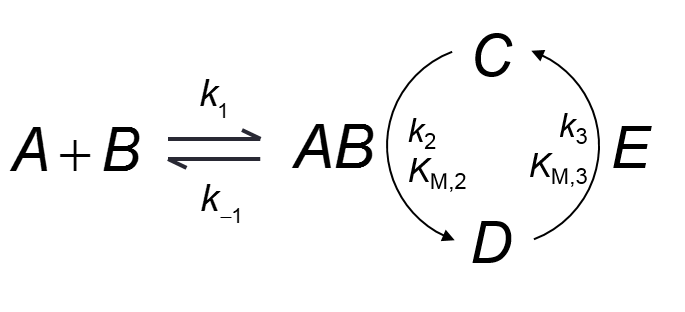

Enzymes act as biological catalysts, increaseing the rate of a chemical reaction by lowering the activation energy required to convert between states.  An enzymatic reaction can be thought of as a special case of the **bimolecular reaction**.  For the bimolecular reaction shown in Eq. 4.1, we can think of A being the enzyme (E) and B being the substrate (S), while AB is the intermediate that breaks down into the enzyme plus the product (P) according to 

Eq. 4.5                                    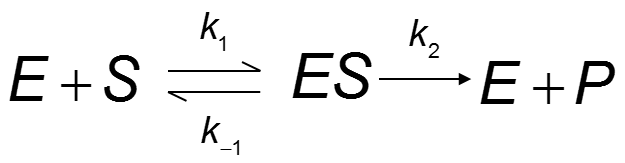

This reaction is more simply written as

Eq. 4.6                                                    

The rate equations for an enzymatic reaction are known as the **Michaelis-Menten equation **

Eq. 4.7                            $\frac{\mathrm{d}\left\lbrack P\right\rbrack }{\mathrm{dt}}=-\frac{\mathrm{d}\left\lbrack S\right\rbrack }{\mathrm{dt}}=\frac{v_{\mathrm{max}} \left\lbrack S\right\rbrack }{K_M +\left\lbrack S\right\rbrack }$   where  $v_{\mathrm{max}} =k_2 {\left\lbrack E\right\rbrack }_{\mathrm{tot}}$

Here $K_M$ is the **Michaelis-Menten** constant and $k_2 \text{ }$is the maximum catalysis rate per enzyme.

The series of ODEs for the reaction scheme shown in Eq. 4.4 are contained in the function *reactionFun2* defined at the end of the file.  

Assume that the initial concentrations and rates from the above example remain, and that the additional values are as follows $\left\lbrack C\right\rbrack \left(0\right)=10\text{ }\mu \mathrm{M}$,$\left\lbrack D\right\rbrack \left(0\right)=2\text{ }\mu \mathrm{M}$, $\left\lbrack E\right\rbrack =3\text{ }\mu \mathrm{M}$, that $k_2 =1\text{ }{\mathrm{s}}^{-1}$, $K_{M,2} =1\mu \mathrm{M}$,  $k_3 =2\text{ }{\mathrm{s}}^{-1}$, $K_{M,3} =3\mu \mathrm{M}$, and solve over a 10 second window

initialConc = [10,5,1,10,2]; %uM, initial concentrations
timespan = [0 10]; %s, time span of the reaction

[T2,Y2] = ode45(@reactionFun2,timespan,initialConc);

%plot the results
figure(1);clf
plot(T2,Y2(:,1),'b-');hold on;
plot(T2,Y2(:,2),'r-')
plot(T2,Y2(:,3),'k-')
plot(T2,Y2(:,4),'g-')
plot(T2,Y2(:,5),'m-')
xlabel('time (sec)','FontSize',12)
ylabel('concentration (\muM)','FontSize',12)
legend('[A]','[B]','[AB]','[C]','[D]')

Note that as the initial concentration proceeds, such that the concentration of *AB* begins to increase, the enzymatic reaction of converting *C* to *D* begins to progress.  What happens if you decrease the bimolecular association rate as above? Change $k_1 =0\ldotp 1\mu {\mathrm{M}}^{-1} {\mathrm{s}}^{-1}$ in *reactionFun2* below and run the code again.

The series of coupled ODEs to be solved are contained in a separate function (*reactionFun* and *reactionFun2*) and are of the following form

Eq. 4.8                                          $\left\lbrack \begin{array}{c}
{\mathit{y'}}_1 \\
{\mathit{y'}}_2 \\
\vdots \\
{\mathit{y'}}_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_1 \left(t,y_1 ,y_2 ,\cdots ,y_n \right)\\
f_2 \left(t,y_1 ,y_2 ,\cdots ,y_n \right)\\
\vdots \\
f_n \left(t,y_1 ,y_2 ,\cdots ,y_n \right)
\end{array}\right\rbrack$

Below are the functions to encode the rate equations in each example above.  For syntax simplicity we have assumed that y1 = *A*, y2 = *B*, y3 = *AB, *y4 = *C*, and y5 =* D*.

function dy = reactionFun(t,y)
% define constants
k1 = 1; %uM^-1s^-1, second-order association rate
k_1 = 0.1; %s^-1, first-order dissociation rate

%initialize the output array, it must be a comumn vector
dy = zeros(3,1); %function output must be a column vector

%series of ODEs
dy(1) = -k1*y(1)*y(2)+k_1*y(3); % dA/dt, from Eq. 4.2
dy(2) = -k1*y(1)*y(2)+k_1*y(3); % dB/dt, from Eq. 4.2
dy(3) = k1*y(1)*y(2)-k_1*y(3);  % dAB/dt, from Eq. 4.3
end

function dy = reactionFun2(t,y)
% define constants
k1 = 1; %uM^-1s^-1, second-order association rate
k_1 = 0.1; %s^-1, first-order dissociation rate
k2 = 1; %s^-1, catalysis rate foer enzyme AB
Km2 = 1; %uM, Michaelis-Menten constant for enzyme AB
k3 = 2; %s^-1, maximum catalysis rate for enzyme E
Km3 = 3; %uM, Michelis-Menten constant for enzyme E
concE = 3; %uM, concentration of enzyme E

dy = zeros(5,1); %function output must be a column vector

%series of ODEs
dy(1) = -k1*y(1)*y(2)+k_1*y(3); % dA/dt, from Eq. 4.2
dy(2) = -k1*y(1)*y(2)+k_1*y(3); % dB/dt, from Eq. 4.2
dy(3) = k1*y(1)*y(2)-k_1*y(3);  % dAB/dt, from Eq. 4.3
dy(4) = -((k2*y(3)*y(4))/(Km2+y(4)))+((k3*concE*y(5))/(Km3+y(5)));  % dC/dt, from Eq. 4.3
dy(5) = ((k2*y(3)*y(4))/(Km2+y(4)))-((k3*concE*y(5))/(Km3+y(5)));  % dD/dt, from Eq. 4.3
end
